# Apply cal from dy120 to prize microCATS

clearvars; close('all');

outdir  =('M:\Mar_Phys\Moorings\PRIZE moorings\data\moor_processed');
indir   =('M:\Mar_Phys\Moorings\PRIZE moorings\data\moor_raw'); 


### Read DY120 caldips first

### SN 9395

fl = [indir filesep '2018\DY120-cal-dips\9395_cal_dip_data.cnv'];

fid = fopen(fl);
tline = fgetl(fid);
lineCounter = 1;
while ischar(tline)
    if strcmp(tline, '*END*')
        break;
    end
    % Read next line
    tline = fgetl(fid);
    lineCounter = lineCounter + 1;
end
fclose(fid);

[cal_temp9395,cal_cond9395,cal_pres9395,cal_timeJ9395,cal_flag9395]=textread(fl,...
            '%f%f%f%f%f','headerlines',lineCounter);

### SN 9396

fl = [indir filesep '2018\DY120-cal-dips\9396_cal_dip_data.cnv'];

fid = fopen(fl);
tline = fgetl(fid);
lineCounter = 1;
while ischar(tline)
    if strcmp(tline, '*END*')
        break;
    end
    % Read next line
    tline = fgetl(fid);
    lineCounter = lineCounter + 1;
end
fclose(fid);

[cal_temp9396,cal_cond9396,cal_pres9396,cal_timeJ9396,cal_flag9396]=textread(fl,...
            '%f%f%f%f%f','headerlines',lineCounter);
        
        
        

### Now read PRIZE instruments 

### 9395

        
fl = [indir filesep '2018' filesep 'SBE37SM-RS232_0370' num2str(9395) '_2019_11_25_precal.cnv'];

fid = fopen(fl);
tline = fgetl(fid);
lineCounter = 1;
while ischar(tline)
    if strcmp(tline, '*END*')
        break;
    end
    % Read next line
    tline = fgetl(fid);
    lineCounter = lineCounter + 1;
end
fclose(fid);

[~,timeJ9395,pres9395,temp9395,cond9395,depth9395,sal9395,dens9395,flag9395]=textread(fl,...
    '%f%f%f%f%f%f%f%f%f','headerlines',lineCounter);


### 9396

fl = [indir filesep '2018' filesep 'SBE37SM-RS232_0370' num2str(9396) '_2019_11_25_precal.cnv'];

fid = fopen(fl);
tline = fgetl(fid);
lineCounter = 1;
while ischar(tline)
    if strcmp(tline, '*END*')
        break;
    end
    % Read next line
    tline = fgetl(fid);
    lineCounter = lineCounter + 1;
end
fclose(fid);

[~,timeJ9396,pres9396,temp9396,cond9396,depth9396,sal9396,dens9396,flag9396]=textread(fl,...
    '%f%f%f%f%f%f%f%f%f','headerlines',lineCounter);


Find in water data within range of salinity of cal dip

ix = cal_pres9396>=10 ; % find dataa deeper than 10 db

cal_C=cal_cond9396(ix);
cal_C=cal_C*(1/100*1000); % convert to ms/cm

id1=cond9396>=min(cal_C);
id2=cond9396<=max(cal_C);
id=id1&id2;

figure;
plot(cond9395(id),'b-')
hold on
plot(cal_C,'r+')



Plot cal vs. data

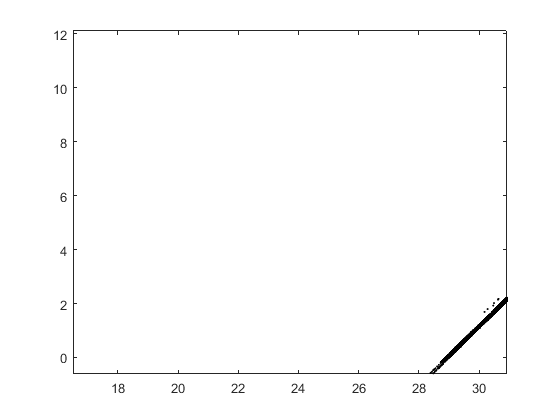

figure;
plot(cond9396,cond9396,'k.');
hold on
plot(cal_cond9396*(1/100*1000),cal_cond9396*(1/100*1000),'r.');